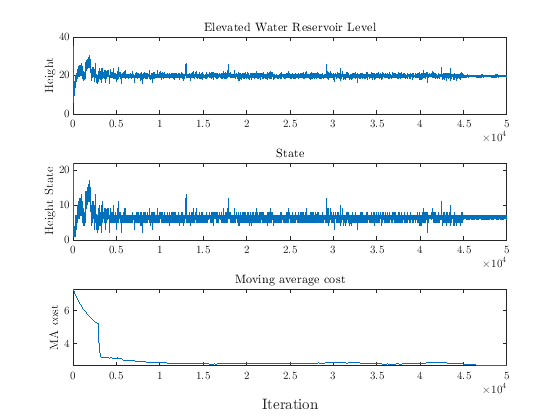

clear all; close all; clc
load("TabularFinalWorkspace.mat")

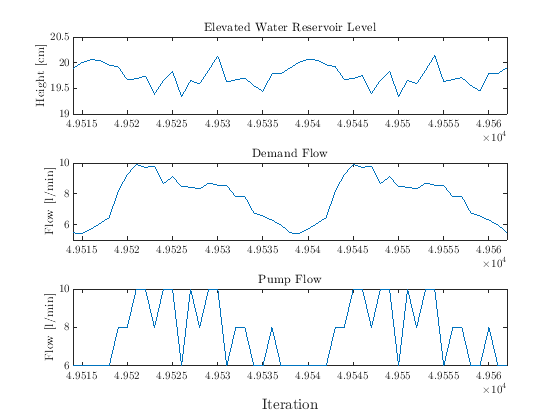




flow = [6 8 10];

for i=1:maxstep
    pflow(i) = flow(pump(i));
end



fig = figure(9);
    ha(1)=subplot(3,1,1);
    plot(actualhi)
    ylabel('Height [cm]')
    ylim([19 20.5]);
    title('Elevated Water Reservoir Level')
    ha(2)=subplot(3,1,2);
    plot(demandvector)
    ylabel('Flow [l/min]')
    title('Demand Flow')
    ha(3)=subplot(3,1,3);
    plot(pflow)
    ylabel('Flow [l/min]')
    title('Pump Flow')
    linkaxes(ha,'x')
    xlim([0.99*maxstep+14 0.99*maxstep+48+14])
    han=axes(fig,'visible','off'); 
    han.XLabel.Visible='on';
    xlabel(han,'Iteration');

    
     fig = figure(19);
    hb(1)=subplot(3,1,1);
    plot(actualhi)
    ylabel('Height [cm]')
    ylim([0 40]);
    title('Elevated Water Reservoir Level')
    hb(2)=subplot(3,1,2);
    plot(Tanklevel)
    ylabel('Height State')
    title('State')
    hb(3)=subplot(3,1,3);
    plot(EPaveragecost(5,:))
    ylabel('MA cost')
    title('Moving average cost')
    linkaxes(hb,'x')

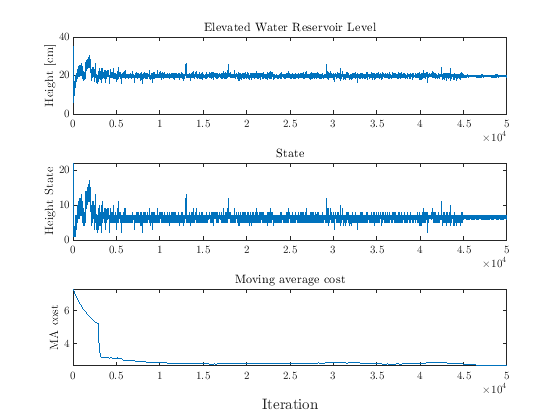

    han=axes(fig,'visible','off'); 
    han.XLabel.Visible='on';
    xlabel(han,'Iteration');
    
    
    
    
    
    figure(20)
    plot(actualhi)
    xlim([0 0.1*maxstep])
    title('Elevated Water Reservoir Level')
    xlabel('Iteration') 
    ylabel('Height [cm]')

    
     figure(21)
    plot(actualhi)
    xlim([0.85*maxstep maxstep])
    title('Elevated Water Reservoir Level')
    xlabel('Iteration') 
    ylabel('Height [cm]')

    
%exportgraphics(figure(9), fullfile('..\..\Report\figures','TabularResults1.pdf'))
%exportgraphics(figure(19), fullfile('..\..\Report\figures','TabularResults2.pdf'))

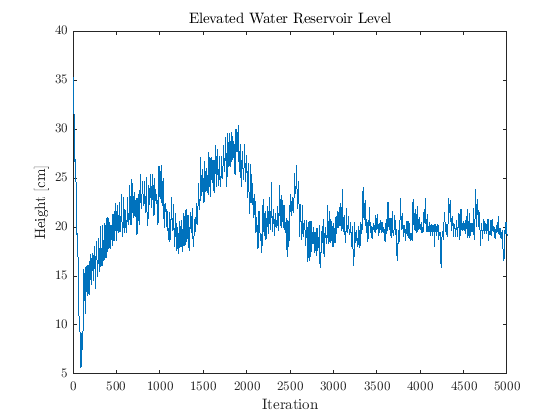

%exportgraphics(figure(20), fullfile('..\..\Report\figures','TabularResults3.pdf'))

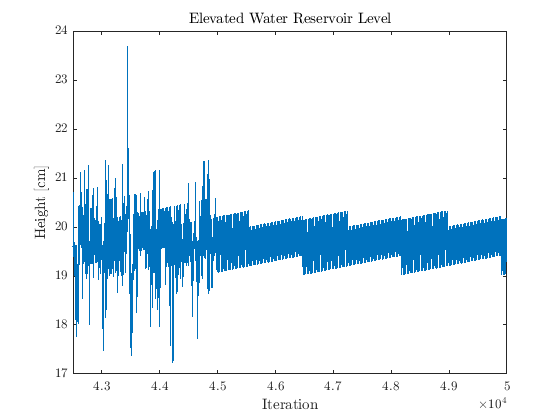

%exportgraphics(figure(21), fullfile('..\..\Report\figures','TabularResults4.pdf'))